# Bleaching and Mortality in the Coral Model

This document is meant to summarize the various definitions of bleaching and mortality which are used during calculations and for generation of figures and tables.  The ultimate goal is to provide a reliable reference which can be used when writing papers or explaining the model outputs.

This will be organized in several sections.

**Notes on notation **

**Bold** indicates variable names, *Italics* indicate file names, and underlining marks errors and likely sources of confusion.

% Monospaced font on grey is live code.
fprintf("%s", "Results will print to the right or below.");

Results will print to the right or below.

## Section 1, Model parameters

The model has many externally-settable parameters defined in *ParameterDictionary.m*, but none of them relate to this document.  That can be considered good, because it keeps the definitions stable from run to run, unless there is an actual code change.  Most are defined in *Coral_Sym_constants_4.mat* in the **bleachParams** variable.

load('mat_files/Coral_Sym_constants_4.mat', ...
     'bleachParams', 'coralSymConstants');
bleachParams

bleachParams = struct with fields:
               sBleach: [0.3 0.3]
               cBleach: [0.1 0.1]
     sRecoverySeedMult: [4 4]
     cRecoverySeedMult: [4 4]
    cSeedThresholdMult: [2 2]
      yearsToMortality: 5


Note that massive and branching corals have separate entries in the data structure, but the values are always the same for both.  Variables starting with "c" apply to corals, and "s" to symbionts.

**sBleach** and **cBleach** are used in these two lines of code from *Clean_Bleach_Stats.m*:               

This specifies that if symbionts drop below 30% of their previous-year minimum or corals drop below 10% of their previous-year minimum, bleaching begins.  This logic is only applied if the coral is not already in a bleached state, and bleaching applies equally whether sB, cB, or both are true.  The year when this happens is recorded as the last bleaching event, but this will be erased if the coral recovers.

**sRecoverySeedMult** and **cRecoverySeedMult** are used in these lines, which are excecuted only when coral is bleached:

which check whether the symbionts and corals are sufficiently above their seed values to be considered recovered.  If both are true, the coral becomes "not bleached" and if it was considered dead, it becomes live.  The last bleaching year is set to "NaN", meaning that this year is only defined for reefs which are still bleached or dead at the end of a run.

**cSeedThresholdMult** is used here

to calculate **seedThresh**, which is in turn used here

to determine whether coral should be considered dead due to low cover alone, as opposed to the relative changes described above.  Note that this only applies to coral, not symbionts.  If this is true, the coral is considered both bleached and dead, and the last bleaching year value is set.  **C_seed** values are described separately, in Section 3.

**yearsToMortality** is renamed **extendedBleaching** in *Clean_Bleach_Stats.m* and used here

to set the mortality flag if coral is bleached and the last bleaching event was "**extendedBleaching**" years ago.  There seems to be an error here. Either the "1" should not be added, or the comparison should be ">=".  As written, **yearsToMortality** = 5 cause to the flag to be set in the 6th year.

## Section 2, Returned values from *Clean_Bleach_Stats.m*

The calculations described in Section 1 return several arrays designed to make further analysis easier.  Their names can be seen in the function signature:

In the text below, the variable indexes are descriptive, and may not match the code.

**C_monthly**(month, coral) contains monthly coral cover for each coral type.  The full C array is at 1/8 month timesteps, and here the decimate function is used to reduce it to a more manageable size.  On return, this array is only used in the per-reef plotting function* Plot_One_Reef.m*.

**S_monthly** is the same, but for symbiont populations.  On return, this array is only used in the per-reef plotting function* Plot_One_Reef.m*.

**C_yearly** is the same, but at a yearly level.  C is reduced by a factor of 8*12.  This is obsolete, as it is returned but never used.  The main program calculates a fresh copy of **C_yearly**!

**bleachEvent**(year, coral) is a boolean array with a true value set whenever a decline in coral or symbionts signals bleaching.  Note that if the bleaching continues, subsequent years are not marked true.  Also note that mortality events based on low cover do not set this true, even though they do update the lastBleaching year value.  On return, this is stored in an intermediate array until all reefs have been computed, and then collected into the 3D array **bleachEvents**(reef, year, coral).

**bleached**(year, coral) reflects bleaching state rather than bleaching events.  It is true for any year when a coral is considered bleached.  On return, this is stored in an intermediate array until all reefs have been computed, and then collected into the 3D array **mortState**(reef, year, coral).

**dead**(year, coral) is true for any year when a coral is considered dead.

On return. each of **bleachEvent**, **bleached**, and **dead** represents the result for a single reef.  These are collected in intermediate arrays until the parallel computation is finished and the combined into the 3D arrays  **bleachEvents**(reef, year, coral), **bleachState**(reef, year, coral), and **mortState**(reef, year, coral).

Note that in *Clean_Bleach_Stats.m* there is no concept of "reef" mortality or bleaching.  That interpretation is added later.

## Section 3, Seed Values

Seed values are treated as minimum values in the integration steps of the model, but are also used to define thresholds in the bleaching and mortality calculations.  The code below is unchanged from *A_Coral_Model.m* except for the addition of print statements and lines containing just a variable.

% Define the seed values below which populations are not allowed to drop.
% 1% of K for massive and 0.1% for branching corals.
% The values are 741,250 and 102,500 square cm of coral per 625 square m of reef.
C_seed = [coralSymConstants.KCm*0.01 coralSymConstants.KCb*0.001];
fprintf('Coral carrying capacities:\n  coralSymConstants.KCm = %d and .KCb = %d', ...
    coralSymConstants.KCm,coralSymConstants.KCb)

Coral carrying capacities:
  coralSymConstants.KCm = 74125000 and .KCb = 1.025000e+08

C_seed

C_seed =    7.4125e+05    1.025e+05


% 10^-5 % of seed, based on having corals at their seed levels as well.
% The values are 222,375 and 41,000 cells per 625 square meters of reef.
msSeed = 10^-7 * coralSymConstants.KSm * C_seed(1);
bsSeed = 10^-7 * coralSymConstants.KSb * C_seed(2);
fprintf('Symbiont carrying capacities:\n  coralSymConstants.KSm = %d and .KSb = %d', ...
    coralSymConstants.KSm,coralSymConstants.KSb)

Symbiont carrying capacities:
  coralSymConstants.KSm = 3000000 and .KSb = 4000000

S_seed = [msSeed bsSeed msSeed bsSeed];
S_seed

S_seed =    2.2238e+05        41000   2.2238e+05        41000


## Section 4, Summary data for tables and figures

Before tables are printed some intermediate values are needed.

**mortState** receives an extra "reef" column which is set true if all coral types are dead.

**bleachState** receives an extra "reef" column which is set true if all coral types are bleached.

**lastYearAlive** is a 1D array containing the year number of the last "false" value in **mortState** for each reef.

**lastBleachEvent**(reef, coral) is the year of the last bleaching event.  This is calculated based on the last year when a reef is not bleached according to **bleachState**, and not based on **bleachEvents**!

**events85_2010** is a 1D array with the number of bleaching events each reef experienced between 1985 and 2010, inclusive.  Note that this counts both branching and massive events, so it is possible to have more than one events in a year!

Next, an boolean array called **frequentBleaching**(reef, year, coral) is built.  This is true when there have been 2 or more events in the previous 10 years. Note: do we really mean the previous 9 years plus the curent year?

These arrays become inputs to map, graph, and table outputs.  Since the plots generated at runtime are used as diagnostics, I'll focus on tabular output.

*Stats_Table.m* creates the end-of-run tables.  The function signature is

where the first 5 arguments are described above. **allLatLon** allows reefs to be grouped by latitude, and the rest are simply used for labeling and storing the results.  All tables are shown with equatorial (<= 7 degrees from the equator), mid (above 7 to <= 15 degrees) and high-latitude subtotals, but the discussion here applies equally to all.

The tables all have year headings across the top.  The descriptions below describe the value used for any year listed.  All values are converted to percentages for display.

- "Permanently bleached reefs as of the date given" displays the number of reefs for which **lastBleachEvent** for massive coral is less than or equal to the current year.

- "Permanent mortality as of the date given" displays the  mortality based on the number of reefs for which **lastYearAlive** is less than or equal to the current year.  This is reef-based.

- "Percentage of reefs with more than one massive coral bleaching event in the previous 10 years" displays  the number of reefs with **frequentBleaching** set to true for either coral type.

- "Percentage of LIVING reefs with more than one bleaching event in the previous 10 years" displays frequentLive, which is calculated as the number of reefs not in permanent mortality (error: this includes reefs which are dead but recover later) divided into the number of reefs with frequent bleaching as defined for the table above.

- "Percentage of reefs with at least one coral type in an unrecovered state" sums all reefs which are either bleached or dead.  Either coral type counts, so a reef with dead or bleached branching coral counts here, even if the massive coral is fine.

- "Percentage of reefs with any form of current bleaching or mortality" uses a combination of several inputs.  The definition first looks at the two coral types separately.  A coral type is considered stressed if it is dead, bleached, or seeing frequent bleaching (any of **mortState**, **bleachState** or **frequentBleaching** is true).  Then a reef is considered stressed only if BOTH coral types are stressed.  The data for this table is stored in the array **allStress**.

## Section 5, Summary data for figures (post-processed)

*Stats_Table.m *also saves a file with the **allStress** values ready for plotting in what becomes Figure 1.  The time granularity of the output is determined by the array **years**, which is every 10 years until 1950 and every year thereafter, when detailStats is true.  When this plot is not needed, the years displayed are a more compact [1950 2000 2016 2050 2075 2100].  The file goes in the directory defined by **outputPath**/bleaching, and the filename is BleachingHistory appended with key run parameters.

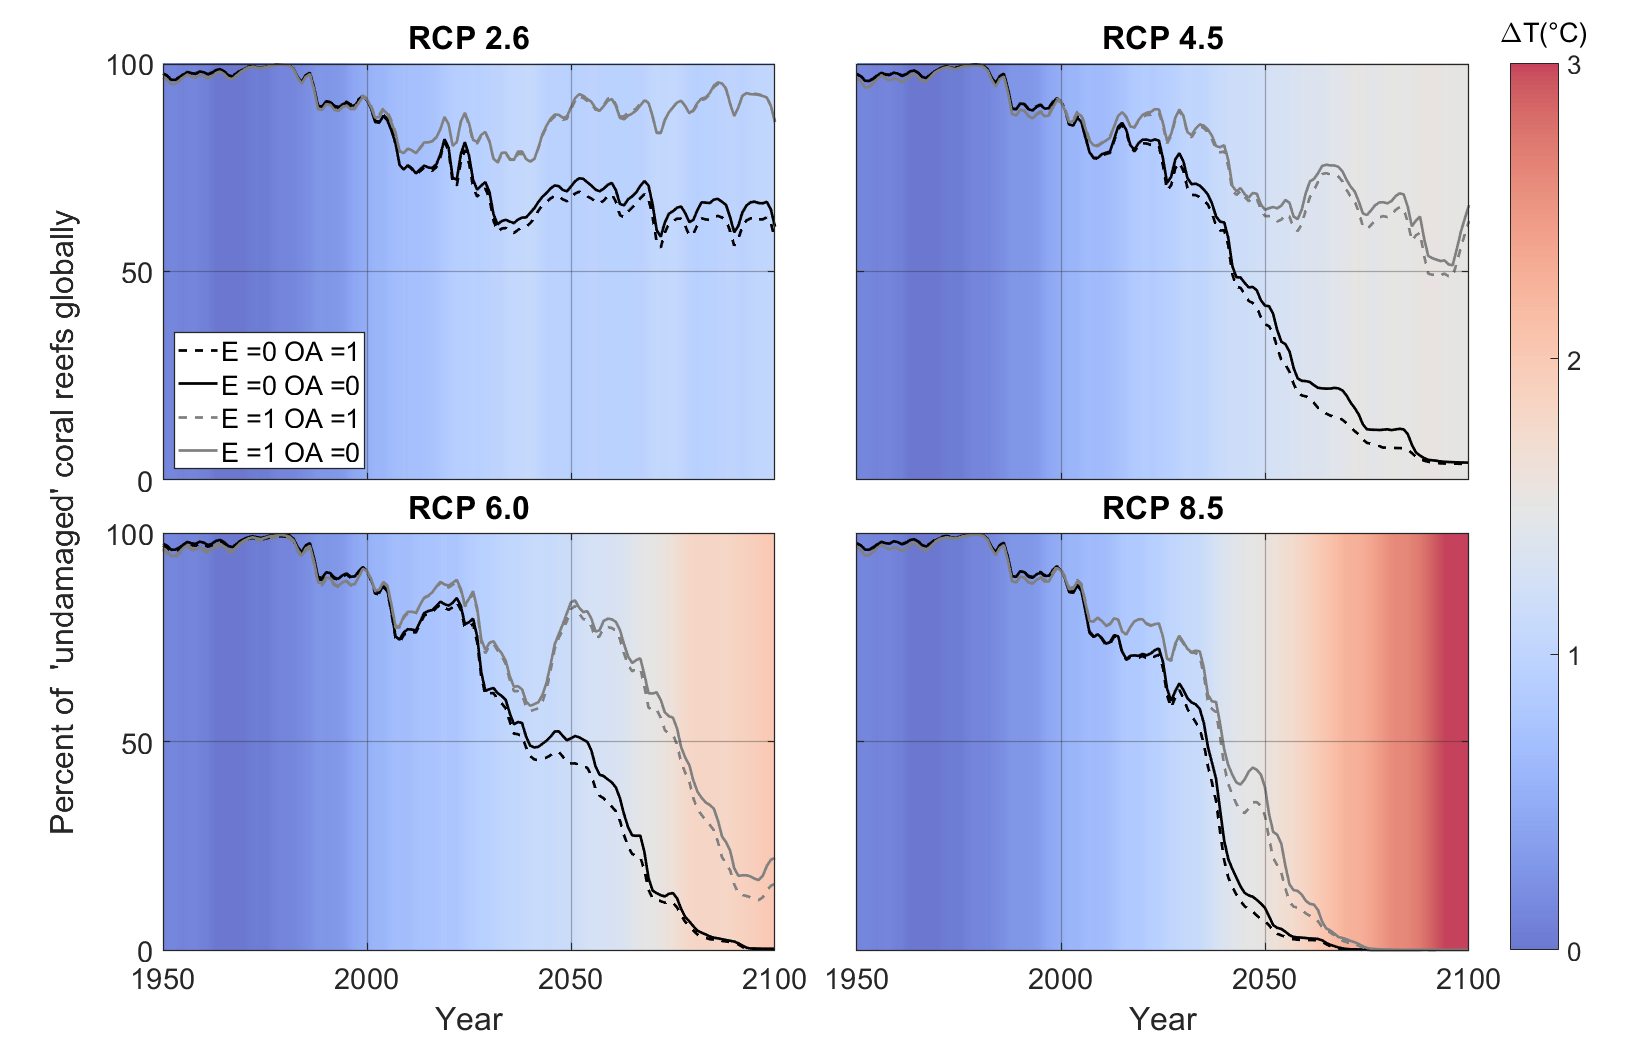

T from 0 to 1.069944e+00 for RCP 2.6
T from 0 to 1.558799e+00 for RCP 4.5
T from 0 to 2.012448e+00 for RCP 6.0
T from 0 to 3.085484e+00 for RCP 8.5


BleachingHistory_Subplots_WithDT()

## Section 6, Summary data for figures (runtime)

Only the coral cover figure is described here, as the other runtime figures are currently only used as diagnostics.

The only input of interest here is C_yearly, the yearly coral cover.  This is neither a maximum nor a minimum, but is the output of 

The function uses "quantile" to find the 5%, 25%, 50%, 75%, and 95% coral cover levels.  Using blue for branching coral and red for massive, it overlays the 5-95% range in pale color, the 25-75% range in a medium intensity, and the median as a solid line.

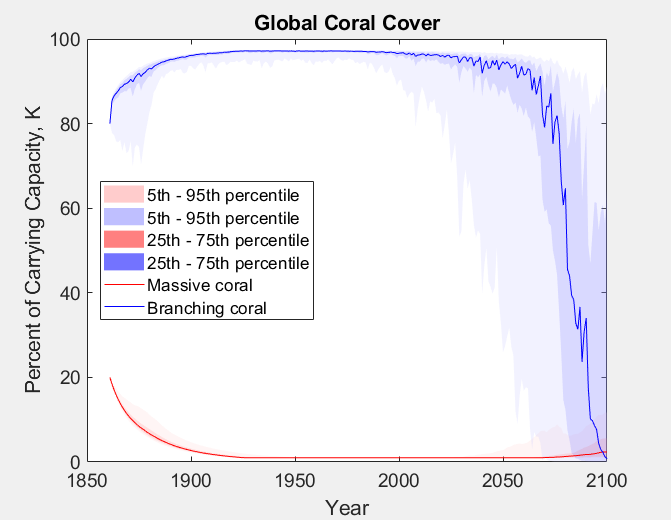

## Section 7, Terms used in tables and figures

Figure 1 uses the values described from array **allStress**, described above, collecting the values from 16 separate model runs.  The background is computed directly from the SST input loaded from *ESM2M_SSTR_JD.mat*.

Figure 2 is a compilation of coral cover history plots output during each run.

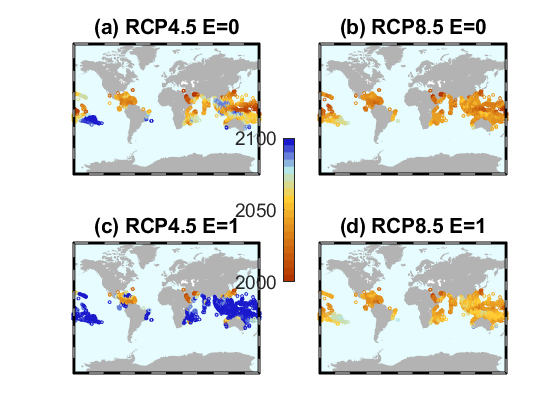

addpath('.\FigureManipulation');  % Edit to run on a different system.
MergeSelectedLastYearMaps

Table 1 combines 2 sets of values.  The main values are percentages of coral mortality in 2100 for various scenarios.  The values are taken from the "Permanent mortality as of the date given" table output after each run.  The value is in the 2100 column and All Reefs row.

The second value is a fraction in parentheses.  It represents the ratio between massive and branching coral cover at the end of each run.  The  values are written to the console and log below the tabular output of each run, labeled "Fraction of reefs dominated by branching coral:".  This is written by a dedicated function

which computes coral cover for each reef and coral type as a fraction of carrying capacity.  It then outputs 3 values.  The first is the mean of the sum of these two fractions, with the sum capped at 1.0 before the mean is taken. The second is percentage of reefs with less than 10% cover.  The third is the value used in the table, which is the fraction of the reefs which have more branching than massive coral relative to carrying capacity.